%Program to find distance travelled by freely falling object due to gravity
%at specified time intervals between given start and end times

% Input data
g = 9.81;

StartTime = input('Input the starting time ');
EndTime = input('Input the ending time ');
Increment = input('Input the time increment ');


% Calculate distance travelled at each time increment
% Create vector of times
time = StartTime:Increment:EndTime;

%Calculate the distances
distance = 1/2 * g * time.^2;

## Create matrix of output data

table = [time;distance]';

% Output the results as a table
disp('Distance Travelled in Free Fall');

Distance Travelled in Free Fall


disp('Time,s     Distance, m');

Time,s     Distance, m


disp(table);

    1.0000    4.9050
    1.0100    5.0036
    1.0200    5.1032
    1.0300    5.2037
    1.0400    5.3052
    1.0500    5.4078
    1.0600    5.5113
    1.0700    5.6157
    1.0800    5.7212
    1.0900    5.8276
    1.1000    5.9351
    1.1100    6.0435
    1.1200    6.1528
    1.1300    6.2632
    1.1400    6.3745
    1.1500    6.4869
    1.1600    6.6002
    1.1700    6.7145
    1.1800    6.8297
    1.1900    6.9460
    1.2000    7.0632
    1.2100    7.1814
    1.2200    7.3006
    1.2300    7.4208
    1.2400    7.5419
    1.2500    7.6641
    1.2600    7.7872
    1.2700    7.9113
    1.2800    8.0364
    1.2900    8.1624
    1.3000    8.2895
    1.3100    8.4175
    1.3200    8.5465
    1.3300    8.6765
    1.3400    8.8074
    1.3500    8.9394
    1.3600    9.0723
    1.3700    9.2062
    1.3800    9.3411
    1.3900    9.4770
    1.4000    9.6138
    1.4100    9.7516
    1.4200    9.8904
    1.4300   10.0302
    1.4400   10.1710
    1.4500   10.3128
    1.4600   10.4555
    1.4700   

## Plot distance against time

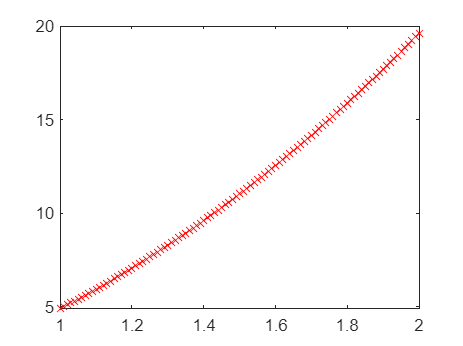

plot(time, distance,'xr');

## Plot distance against time with 10% margin around plot

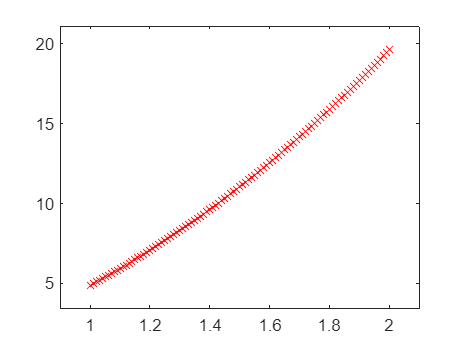

xrange = time(end) - time(1);
yrange = distance(end) - distance(1);
xmin = time(1) - 0.1*xrange;
xmax = time(end) + 0.1*xrange;
ymin = distance(1) - 0.1*yrange;
ymax = distance(end) + 0.1*yrange;
plot(time, distance,'xr');
axis([xmin, xmax, ymin, ymax]);